# **RS-HL-1: Generate Contact Chart of Given Constellation**

**Hongseok Kim**

**Ver 1.0**

**Last Revised: 6/5/2048**

## Revision History

Ver 1.0: Initial Draft [6/5/2048]

## Scope

## Interface Specification

clc; clear;
addpath('~/Desktop/RS_Local/RS_HL/')

## I. Input information

### I.1 Time Parameter

% Initial Epoch Definition

Year = 2024;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(24);
steptime = 15; % seconds

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);

time_parameters.startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
time_parameters.duration = duration;
time_parameters.steptime = steptime;

scenario = scenario_initalization(time_parameters);



### I.2 Satellite Constellation - Walker Configuration (48 SATs in Single Orbit)

% Intial Orbit Settings

Altitude = 500; % (km)
Eccentricity = 1e-5;
Inclinaton = 97.4022; % (deg)
RAAN = 90;  % (deg)
AOP = 0; % (deg)

% Number of satellites
number_of_SATs = 24;

% Satellite Characteristics - This will entail -1, -2, ... for
% constallation
satellite_name = "RS-1";

% Orbit Propagator
Orbit_Propagator = 'SGP4';


orbit_information.SMA = Altitude*1000 + 6378000;
orbit_information.ecc = Eccentricity;
orbit_information.inc = Inclinaton;
orbit_information.RAAN = RAAN;
orbit_information.AOP = AOP;

% Generate First Stream of Satellites
satellites_orbit_1 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);


% Generate Second Steram of Satellites
RAAN = 105;
orbit_information.RAAN = RAAN;
satellite_name = "RS-2";
satellites_orbit_2 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);

% Merge Satellite Informations
satellites = [satellites_orbit_1, satellites_orbit_2];



### I.4 Ground Station Location

gs_info = ["Austin", 30.2672, -97.7431, 15;
           "New York", 40.7128, -74.0060, 10;
           "Los Angeles", 34.0522, -118.4837, 71;
           "Chicago", 41.8781, -87.6298, 181;
           "Houston", 29.7604, -95.3698, 30;
           "Phoenix", 33.4484, -112.0740, 331;
           "Philadelphia", 39.9526, -75.1652, 12;
           "San Antonio", 29.4481, -98.4936, 198;
           "San Diego", 32.7157, -117.1611, 22;
           "Dallas", 32.7767, -96.7970, 137;
           "London", 51.5074, -0.1278, 35;
           "Tokyo", 35.6895, 139.6917, 6;
           "Paris", 48.8566, 2.3522, 35;
           "Moscow", 55.7558, 37.6176, 155;
           "Sydney", -33.8688, 151.2093, 19;
           "Toronto", 43.6511, -79.3830, 76;
           "Berlin", 52.5200, 13.4050, 34;
           "Rome", 41.9028, 12.4964, 17;
           "Seoul", 37.5665, 126.9780, 23;
           "Mumbai", 19.0760, 72.8777, 14;
           "Beijing", 39.9042, 116.4074, 43;
           "Mexico City", 19.4326, -99.1332, 2240;
           "São Paulo", -23.5505, -46.6333, 780;
           "Bangkok", 13.7563, 100.5018, 2;
           "Istanbul", 41.0082, 28.9784, 39;
           "Cairo", 30.0444, 31.2357, 23;
           "Dubai", 25.2769, 55.2963, 4;
           "Singapore", 1.3521, 103.8198, 15;
           "Hong Kong", 22.3193, 114.1694, 39;
           "Sydney", -33.8688, 151.2093, 19];



gs = groundStation(scenario,"Name",gs_info(:,1), ...
                        "Latitude",str2double(gs_info(:,2)), ...
                        "Longitude", str2double(gs_info(:,3)), ...
                        "Altitude", str2double(gs_info(:,4)), ...
                        "MinElevationAngle", 15);


## II. Access Information Generation

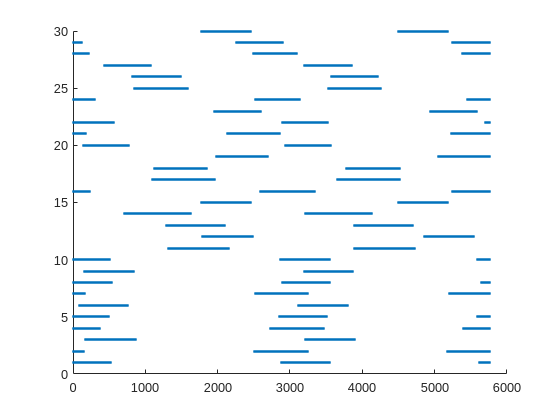

number_of_cities =length(gs);

time_vector = scenario.StartTime:seconds(scenario.SampleTime):scenario.StopTime;
gs_name_vector = gs_info(:,1);

access_matrix = zeros(length(gs_name_vector), length(time_vector));

access_table = [];

for i = 1:number_of_cities
access_info = access(gs(i),satellites);
access_single_gs = accessIntervals(access_info);
  for j = 1:height(access_single_gs(:,1))
    contact_start_index = (table2array(access_single_gs(j,4)) - scenario.StartTime)/seconds(scenario.SampleTime);
    contact_end_index = (table2array(access_single_gs(j,5)) - scenario.StartTime)/seconds(scenario.SampleTime);
     for k = contact_start_index+1:contact_end_index+1
       access_matrix(i,k) = access_matrix(i,k) + 1;
     end
  end

access_table = [access_table; access_single_gs];
end


access_information.access_Intervals = access_table;

graph_plot = [];

access_table;
figure;
for i = 1:length(access_matrix(:,1))
  for j = 1:length(access_matrix(1,:))

    if(access_matrix(i,j) ~= 0)
    graph_plot = [graph_plot;j,i];
    end

  end
end

scatter(graph_plot(:,1),graph_plot(:,2),'.')

## III. Data Visualization

% play(scenario)

## IV. Data Analysis